# Example 5.7: Uncertainty Quantification for Heat Capacity

Note: this script reproduces Example 5.7 (Section 5.2.3) of **Statistics for Chemical Engineers**: confidence ellipses for the parameters and confidence intervals for the predictions. Victor Z UW-Madison, 2020 linear regression and uncertainty quantification for heat capacity

clc; clear all; close all hidden;

## Data

generate data (true model is Cp=a0+a1*T+a2*T^2) CP in cal/mol-K and T in K

a0=+0.6190e+1;
a1=+0.2923e-2;
a2=-0.7052e-6;
theta=[a0,a1,a2]'

theta =      6.190000000000000e+00
     2.923000000000000e-03
    -7.052000000000000e-07



% 3 sets of experiments at T=300K, T=600K, and T=900K
n=10;
N=3*n;
x1=linspace(300,300,n)';
x2=linspace(600,600,n)';
x3=linspace(900,900,n)';
 x=[x1; x2; x3];
    
% generate true outputs 
rng(0);
y1=a0+a1*x1+a2*x1.^2;
y2=a0+a1*x2+a2*x2.^2;
y3=a0+a1*x3+a2*x3.^2;
ytrue=[y1; y2; y3];

% add random noise to true outputs
sigma=0.1;
y=ytrue+normrnd(0,sigma,N,1);

% construct input and output data matrix for MLE
xsq=x.^2;
X=[ones(N,1),x,xsq];
Y=y;

## Estimate

obtain best fit parameters

thetaest=inv(X'*X)*X'*Y;
Yhat=X*thetaest;
e=Y-Yhat;
pd = fitdist(e,'Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 2.66927e-13   [-0.0481496, 0.0481496]
    sigma =    0.128947   [0.102694, 0.173345]


sig2=(pd.sigma)^2;
C=inv(X'*X)*sig2;

## Confidence ellipses of the parameters

visualize 1-2 pair

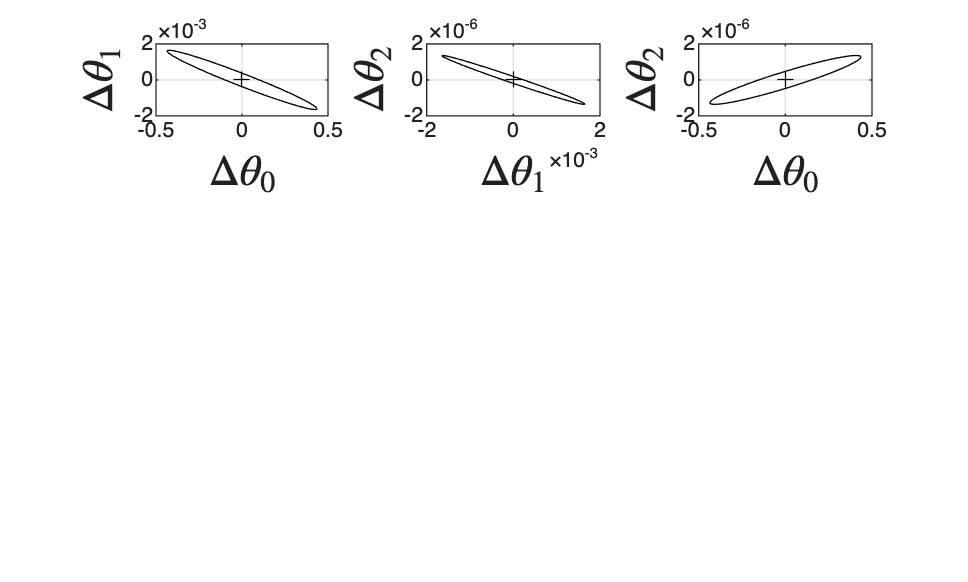

Sigma=C(1:2,1:2);
mu= [0,0];

% compute the 95% confidence interval ellipse
alpha = 0.95; % confidence 
n = 2; % dimension of variable
A = inv(Sigma); % inverse covariance
b = chi2inv(alpha, n); % confidence level on 2d from chi2 distribution
[xe, ye, major, minor, bbox] = ellipse(A, b, 100, mu); % ellipse

% plot the ellipse
figure(1);
subplot(3,3,1)
plot(xe,ye,'black') % plot the ellipse
hold on
plot(0,0,'black+')
grid on
hold on
xlabel('$\Delta \theta_0$','Interpreter','latex','FontSize',16)
ylabel('$\Delta \theta_1$','Interpreter','latex','FontSize',16)

% visualize 2-3 pair
Sigma=C(2:3,2:3);
mu= [0,0];

% compute the 95% confidence interval ellipse
alpha = 0.95; % confidence 
n = 2; % dimension of variable
A = inv(Sigma); % inverse covariance
b = chi2inv(alpha, n); % confidence level on 2d from chi2 distribution
[xe, ye, major, minor, bbox] = ellipse(A, b, 100, mu); % ellipse

% plot the ellipse
figure(1);
subplot(3,3,2)
plot(xe,ye,'black') % plot the ellipse
hold on
plot(0,0,'black+')
grid on
hold on
xlabel('$\Delta \theta_1$','Interpreter','latex','FontSize',16)
ylabel('$\Delta \theta_2$','Interpreter','latex','FontSize',16)

% visualize 1-3 pair
Sigma=C([1,3],[1,3]);
mu= [0;0];

% compute the 95% confidence interval ellipse
alpha = 0.95; % confidence 
n = 2; % dimension of variable
A = inv(Sigma); % inverse covariance
b = chi2inv(alpha, n); % confidence level on 2d from chi2 distribution
[xe, ye, major, minor, bbox] = ellipse(A, b, 100, mu); % ellipse

% plot the ellipse
figure(1);
subplot(3,3,3)
plot(xe,ye,'black') % plot the ellipse
grid on
hold on
plot(0,0,'black+')
hold on
xlabel('$\Delta \theta_0$','Interpreter','latex','FontSize',16)
ylabel('$\Delta \theta_2$','Interpreter','latex','FontSize',16)

print -depsc ch5_ellipsoids_heat_capacity.eps


% parameters confidence 95% intervals (boundingbox)
% compare against true parameters
chi= chi2inv(0.95,3) 

chi =      7.814727903251178e+00

conf=sqrt(diag(C)*chi)

conf =      4.968725725615350e-01
     1.880745412976038e-03
     1.551212672084099e-06


Confth=[thetaest-conf,thetaest+conf,theta]

Confth =      5.701594838013638e+00     6.695339983136708e+00     6.190000000000000e+00
     1.298623284103759e-03     5.060114110055835e-03     2.923000000000000e-03
    -2.511410449752778e-06     5.910148944154205e-07    -7.052000000000000e-07



% parameters confidence 95% intervals (marginals)
% compare against true parameters
chi= chi2inv(0.95,1)

chi =      3.841458820694126e+00

conf=sqrt(diag(C)*chi)

conf =      3.483663391603545e-01
     1.318624594296659e-03
     1.087583234967482e-06


Confth=[thetaest-conf,thetaest+conf,theta]

Confth =      5.850101071414818e+00     6.546833749735527e+00     6.190000000000000e+00
     1.860744102783137e-03     4.497993291376456e-03     2.923000000000000e-03
    -2.047781012636161e-06     1.273854572988031e-07    -7.052000000000000e-07



% outputs confidence 95% intervals 
% compare against predicted and measured outputs
 chi= chi2inv(0.95,N)

chi =      4.377297182574218e+01

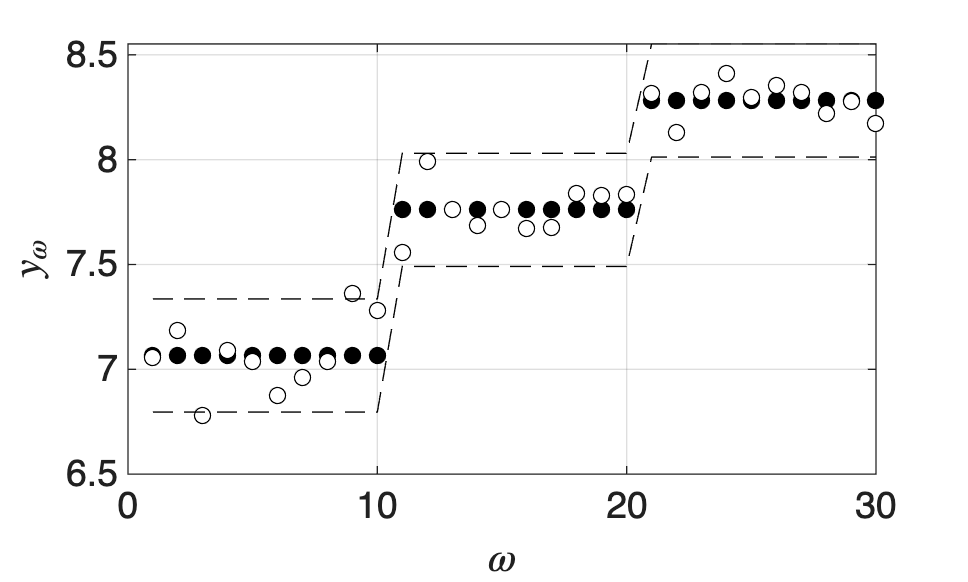

 Cy=X*C*X';
 conf=sqrt(diag(Cy)*chi);
 Confy=[Yhat-conf,Yhat+conf,Yhat,Y];
 
figure(3)
plot(Yhat,'blacko','MarkerFaceColor','black')
hold on
plot(y,'blacko','MarkerFaceColor','w')
hold on
plot(Yhat-conf,'black--','MarkerFaceColor','w')
hold on
plot(Yhat+conf,'black--','MarkerFaceColor','w')
grid on
xlabel('$\omega$','Interpreter','latex','FontSize',16)
ylabel('$y_\omega$','Interpreter','latex','FontSize',16)
set(gca,'FontSize',14)
print -deps ch5_heat_capacity_outputs.eps


% try matlab built-in functions
X = [x xsq];
Y = y;
lm = fitlm(X,Y,'linear')

lm = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                         Estimate                    SE                     tStat                   pValue       
                   _____________________    ____________________    _____________________    ____________________
    (Intercept)     6.19846741057518e+00    1.84206610162022e-01     3.36495384455705e+01    1.39254411704646e-23
    x1              3.17936869707999e-03    6.97252688583817e-04     4.55985147011420e+00    9.93815056797271e-05
    x2             -9.60197777668347e-07    5.75084324924367e-07    -1.66966431887120e+00    1.06541229948751e-01

Number of observations: 30, Error degrees of freedom: 27
Root Mean Squared Error: 0.134
R-squared: 0.939,  Adjusted R-Squared: 0.935
F-statistic vs. constant model: 20


%  get parameter confidence intervals
CI=coefCI(lm)

CI =      5.820506666507359e+00     6.576428154643007e+00
     1.748724352945792e-03     4.610013041214195e-03
    -2.140173345097628e-06     2.197777897609344e-07


## Note

As in the book, the intervals for the predicted outputs are wide even though those of the parameters are small, because the measurement noise is large.